## Regularization

Q:What is **Regularization**?

A: **Regularization** is a technique that **prevents the model from overfitting **on the data by adding a penalty to the weights of model.

Q: What types of regularization exists?

A: There are **3 **main types of **regularization:**

- **Lasso **or **L1 norm**

- **Ridge **or **L2 norm**

- **Dropout**, which we will see in **Deep learning.**

**In this notebook we will examine the use of the Ridge Regression.**

load carbig
feature_units = ["ms/" "lt" "HP"];
feature_names = ["Acceleration" "Displacement" "Horsepower"];
X = [Acceleration Displacement Horsepower];
y = MPG;


% Since the dataset contains missing values, NaNs, we need to remove them
% from the training process
indexes_y = isnan(y);
sum(indexes_y, 1);
y = y(~indexes_y);
X = X(~indexes_y, :);
indexes_x = isnan(X);
sum(indexes_x, 1);

X = X(~any(indexes_x,2), :);
y = y(~any(indexes_x,2), :);


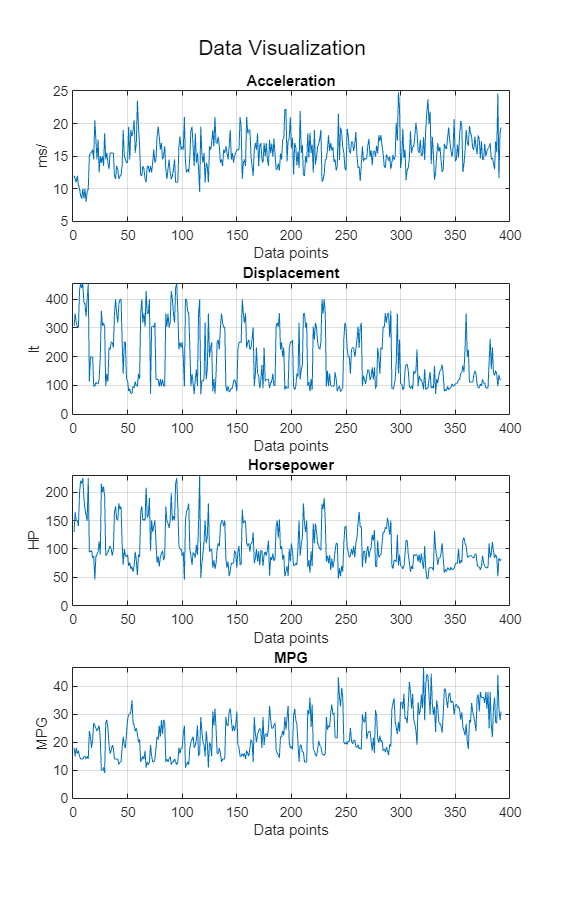

% Visualize the data 
f = figure;
f.Position(3:4) = [2500, 4000];
%f.set
sgtitle("Data Visualization")

for feature=1:3
    
    subplot(4, 1, feature)
    p=plot(X(:,feature));
    
    title(feature_names(feature))
    grid on
    p.DisplayName = feature_names(feature);
    xlabel("Data points")
    ylabel(feature_units(feature))
end
subplot(4, 1, 4)
p=plot(y);

title('MPG')
grid on
p.DisplayName = 'MPG';
xlabel("Data points")
ylabel('MPG')

n = length(y);
rng('default') % For reproducibility
c = cvpartition(n,'HoldOut',0.3);
idxTrain = training(c, 1);
idxTest = ~idxTrain;

bias_term = ones(size(X,1),1);
X_with_bias = cat(2,bias_term,X);

b = regress(y(idxTrain), X_with_bias(idxTrain,:));

disp("The siple multi-regression coefs are:")

The siple multi-regression coefs are:


disp(b')

   47.6108   -0.4842   -0.0395   -0.0862



y_multi_hat = X_with_bias(idxTrain,:) * b;
[error, error_std] = rmse(y(idxTrain), y_multi_hat);

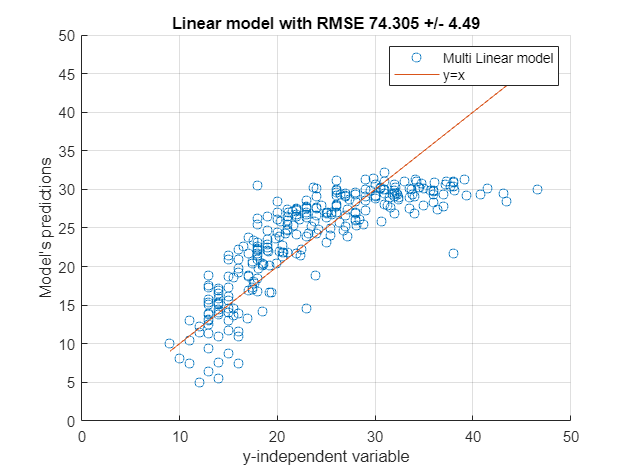

x_line = min(y):max(y);
figure
hold on
scatter(y(idxTrain), y_multi_hat, DisplayName="Multi Linear model")
plot(x_line, x_line, DisplayName="y=x")
grid on
xlabel('y-independent variable')
ylabel("Model's predictions")
legend()
title_text = sprintf("Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([0, 50])
ylim([0, 50])

k = 5;
ridge_b = ridge(y(idxTrain), X(idxTrain,:), k, 0);
disp("The ridge multi-regression coefs are:")

The ridge multi-regression coefs are:


disp(ridge_b')

   46.6536   -0.4443   -0.0389   -0.0840



y_ridge_hat = ridge_b(1) + X(idxTrain,:) *ridge_b(2:end);

[error, error_std] = rmse(y(idxTrain), y_ridge_hat);

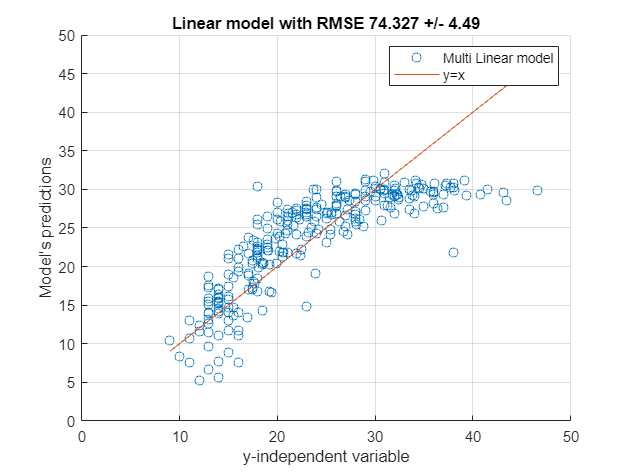

x_line = min(y):max(y);
figure
hold on
scatter(y(idxTrain), y_ridge_hat, DisplayName="Multi Linear model")
plot(x_line, x_line, DisplayName="y=x")
grid on
xlabel('y-independent variable')
ylabel("Model's predictions")
legend()
title_text = sprintf("Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([0, 50])
ylim([0, 50])

## Let's test both models on the unseen data

y_multi_hat_test = X_with_bias(idxTest,:) *b;

y_ridge_hat_test = ridge_b(1) + X(idxTest,:) *ridge_b(2:end);

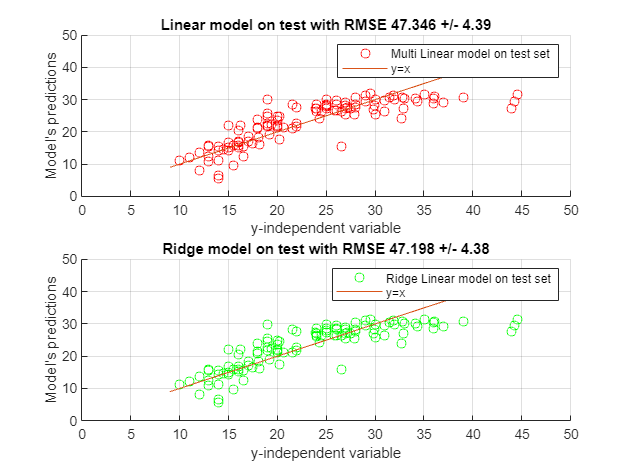

figure
subplot(2, 1, 1)
[error, error_std] = rmse(y(idxTest), y_multi_hat_test);   
hold on
scatter(y(idxTest), y_multi_hat_test, 'r', DisplayName="Multi Linear model on test set")
plot(x_line, x_line, DisplayName="y=x")
grid on
xlabel('y-independent variable')
ylabel("Model's predictions")
legend()
title_text = sprintf("Linear model on test with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([0, 50])
ylim([0, 50])


subplot(2, 1, 2)
hold on
[error, error_std] = rmse(y(idxTest), y_ridge_hat_test);
scatter(y(idxTest), y_ridge_hat_test, 'g', DisplayName="Ridge Linear model on test set")
plot(x_line, x_line, DisplayName="y=x")
grid on
xlabel('y-independent variable')
ylabel("Model's predictions")
legend()
title_text = sprintf("Ridge model on test with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([0, 50])
ylim([0, 50])

function [error, error_std] = rmse(y, y_hat)
    error = round(sqrt(mean(sum((y - y_hat).^2))), 3);
    error_std = round(std(y - y_hat), 3);
end